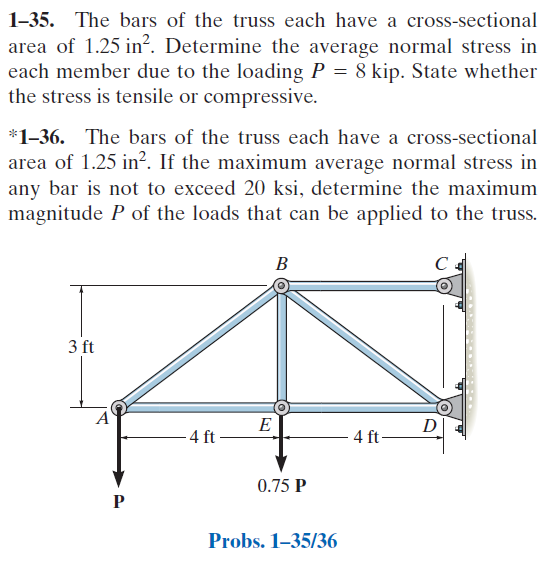

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-35P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-1-problem-35P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

jointA = [0 0]*u.ft;
jointB = [4 3]*u.ft;
jointC = [8 3]*u.ft;
jointD = [8 0]*u.ft;
jointE = [4 0]*u.ft;

# member data

P = 8*u.kip;
E = sym('E');
A = 1.25*u.in^2;

# truss

t = Truss;
t = t.add('reaction', 'Rc', {'Rcx' 'Rcy'}, jointC);
t = t.add('reaction', 'Rd', {'Rdx' 'Rdy'}, jointD);
t = t.add('concentrated', 'Pa', [0 -P], jointA);
t = t.add('concentrated', 'Pe', [0 -0.75*P], jointE);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fae', jointA, jointE, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fbd', jointB, jointD, E, A);
t = t.add('member', 'Fbe', jointB, jointE, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & \frac{9830.4}{\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}}\\ \mathrm{vA} & -\frac{84352.0}{\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}}\\ \mathrm{uB} & -\frac{13516.8}{\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}}\\ \mathrm{vB} & -\frac{40422.4}{\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}}\\ \mathrm{uC} & 0\\ \mathrm{vC} & 0\\ \mathrm{uD} & 0\\ \mathrm{vD} & 0\\ \mathrm{uE} & \frac{4915.2}{\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}}\\ \mathrm{vE} & -\frac{42496.0}{\text{E}}\,\frac{\mathrm{kip}}{\mathrm{ft}} \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m, 4) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 13.33\,\mathrm{kip}\\ \mathrm{Fae} & -10.67\,\mathrm{kip}\\ \mathrm{Fbc} & 29.33\,\mathrm{kip}\\ \mathrm{Fbd} & -23.33\,\mathrm{kip}\\ \mathrm{Fbe} & 6.0\,\mathrm{kip}\\ \mathrm{Fde} & -10.67\,\mathrm{kip} \end{array}\right)$$

la_f_c_vpa = vpa(la.f.c, 4) %#ok<NASGU> 

$$la\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Rc} & 29.33\,\mathrm{kip} & 0 & 0\\ \mathrm{Rd} & -29.33\,\mathrm{kip} & 14.0\,\mathrm{kip} & 0\\ \mathrm{Pa} & 0 & -8.0\,\mathrm{kip} & 0\\ \mathrm{Pe} & 0 & -6.0\,\mathrm{kip} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c, 4) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 10.67\,\mathrm{kip} & 8.0\,\mathrm{kip} & 0\\ \mathrm{Fae} & -10.67\,\mathrm{kip} & 0 & 0\\ \mathrm{Fbc} & 29.33\,\mathrm{kip} & 0 & 0\\ \mathrm{Fbd} & -18.67\,\mathrm{kip} & 14.0\,\mathrm{kip} & 0\\ \mathrm{Fbe} & 0 & -6.0\,\mathrm{kip} & 0\\ \mathrm{Fde} & 10.67\,\mathrm{kip} & 0 & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m, 4) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Rc} & 29.33\,\mathrm{kip}\\ \mathrm{Rd} & 32.5\,\mathrm{kip}\\ \mathrm{Pa} & 8.0\,\mathrm{kip}\\ \mathrm{Pe} & 6.0\,\mathrm{kip} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fae} & 0\\ \mathrm{Fbc} & 88\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fbd} & 112\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fbe} & 24\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fde} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Rc} & 0 & 0 & -88\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Rd} & 0 & 0 & 112\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pa} & 0 & 0 & 0\\ \mathrm{Pe} & 0 & 0 & -24\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fae} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & -88\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fbd} & 0 & 0 & 112\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fbe} & 0 & 0 & -24\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fde} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Rc} & 88\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Rd} & 112\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pa} & 0\\ \mathrm{Pe} & 24\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa la_f_c_vpa ma_f_c_vpa la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;